# Тесты

## Тест 1(матрица 3х3)

n_1 = 3;
A = [[1e-1 2e-2 3e-2];
    [4e-2 5e-1 6e-2];
    [7e-2 8e-2 9e-1]];
b_1 = ones(n_1,1);
epsilon_1 = 1e-12;
x_1_si = simple_iteration(A,b_1,epsilon_1);

Метод простой итерации
Количество итераций:
    23



x_1_z = zeidel(A,b_1,epsilon_1);

x_1_si =    9.685534591195079
   1.194968553459179
   0.251572327044079


Метод Зейделя
Количество итераций: 
    10



Решение методом простой итерации:

x_1_si

Решение методом Зейделя:

x_1_z

x_1_z =    9.685534591194822
   1.194968553459136
   0.251572327044035


ans =    9.690427643843989
   1.196670484815301
   0.234127530643162


## Тест 2 (Разреженная матрица 50х50)

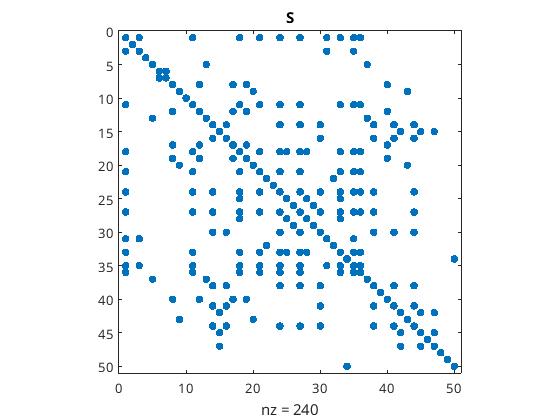

n  = 50;
R = rand(n, 1, 'double');
%S = sprandsym(n, 0.1, R);
spy(S), title('S');

epsilon_2 = 1e-12;
b_2 = ones(n, 1);

x_2_si = simple_iteration(S, b_2, epsilon_2);

Метод простой итерации
Количество итераций:
   402



x_2_z = zeidel(S, b_2, epsilon_2);

x_2_si =    4.092028857716894
   1.489177473631927
   5.062928155672883
  68.557136602713570
   1.268513256779357
   1.680852016230037
   1.484056769219676
   1.397287264045826
   1.217045587530236
   1.126980779295242


Метод Зейделя
Количество итераций: 
   172



Решение методом простой итерации:

x_2_si

Решение методом Зейделя:

x_2_z

x_2_z =    4.092028857716865
   1.489177473631927
   5.062928155672884
  68.557136602713570
   1.268513256779357
   1.680852016230037
   1.484056769219676
   1.397287264045826
   1.217045587530236
   1.126980779295242


## Тест 3 (матрица Гильберта 10х10) 

n_2 = 10;
H = hilb(n_2);
e = ones(n_2, 1);
b_3 = H*e;
epsilon_3 = 1e-12;
x_3_si = simple_iteration(H,b_3,epsilon_3);

Метод простой итерации
Ошибка: спектральный радиус > 1
Количество итераций:
     0



x_3_si =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


x_3_z = zeidel(H,b_3,epsilon_3);

Метод Зейделя
Количество итераций: 
   110653511



Решение методом Зейделя и погрешность решения:

x_3_z

x_3_z =    0.999999998678007
   1.000000175979245
   0.999996275111943
   1.000028396163223
   0.999901229677233
   1.000160261644391
   0.999921790865296
   0.999901992266036
   1.000138260812122
   0.999951610992214


norm(x_3_z-e)

ans =      2.709969595416561e-04
